# Analysis of Discrete-Time Systems

clear all; 
clc; 
close all;

set(groot, 'defaultTextInterpreter', 'LaTeX');
set(groot, 'DefaultAxesTickLabelInterpreter', 'LaTeX');

format long; 

Difference equation (sampling frequency = 8KHz):


$$y(n)=x(n)-x(n-1)$$


fs = 8000;          % sampling frequency
Ts = 1/fs;          % sampling period

Z  = [1, 0,-1];       % coefficients of the numerator polynomial: (1)*z^0 + (-1)*z^-1 
N  = 1;             % coefficients of the denominator polynomial: (1)*z^0
f_points = 1000;                        % number of frequency poinbts to consider
[H, f]   = freqz(Z,N,f_points,fs);      % computing the frequency response

Magnitude response:

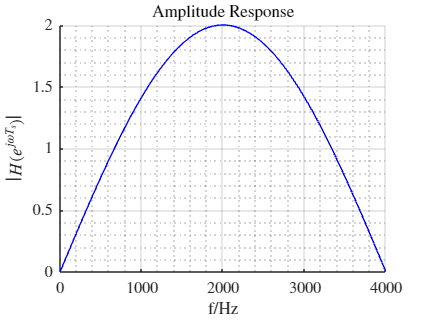

fig = figure;
set(fig,'color','w');
plot(f,abs(H),'color','blue');                         
grid on; grid minor;
box off;
xlabel('f/Hz','Interpreter','latex');
ylabel('$\left| H(e^{j\omega T_s}) \right|$','Interpreter','latex');
title('Amplitude Response','Interpreter','latex','FontWeight','Normal');

Phase response:

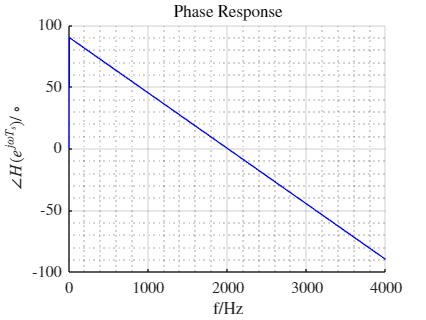

fig = figure;
set(fig,'color','w');
plot(f,angle(H)*180/pi,'color','blue');       
grid on; grid minor;
box off;
xlabel('f/Hz','Interpreter','latex');
ylabel('$ \angle H(e^{j\omega T_s})/ {\circ} $','Interpreter','latex');
title('Phase Response','Interpreter','latex','FontWeight','Normal');

Complex exponential representation:

$y(n) = x(n)-x(n-1)$, $x(n)=Ae^{j(\omega n T_s +\phi)}$


$$H(e^{j \omega T_s})=1-e^{-j \omega T_s}
$$
 


$$| H(e^{j \omega T_s})|=2sin(\omega T_s/2))=2sin(\pi f/f_s))$$


Computing gain (Nyquist):

f_vec = [0,1,2,3,4]*1000;
H_abs = 2*sin(pi*f_vec/fs)'

H_abs =                    0
   0.765366864730180
   1.414213562373095
   1.847759065022573
   2.000000000000000


Magnitude response (Complex exponential):

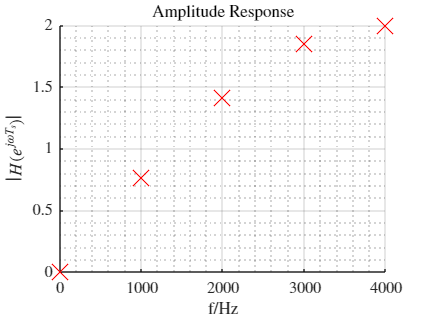

fig = figure;
set(fig,'color','w');
plot(f_vec,H_abs,'x','MarkerSize',14,...
    'MarkerEdgeColor','red');   
grid on; grid minor; box off;
xlabel('f/Hz','Interpreter','latex');
ylabel('$\left| H(e^{j\omega T_s}) \right|$','Interpreter','latex');
title('Amplitude Response','Interpreter','latex','FontWeight','Normal');

Phase response:

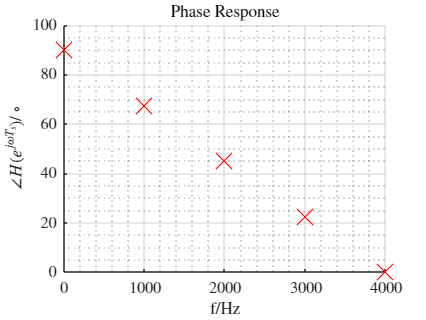

phase = atan(cos(pi*f_vec/fs)./sin(pi*f_vec/fs))*180/pi;
fig = figure;
set(fig,'color','w');
plot(f_vec,phase,'x','MarkerSize',14,...
    'MarkerEdgeColor','red');   
grid on; grid minor; box off;
xlabel('f/Hz','Interpreter','latex');
ylabel('$ \angle H(e^{j\omega T_s})/ {\circ} $','Interpreter','latex');
title('Phase Response','Interpreter','latex','FontWeight','Normal');

The filter output for two sinusoidal input signals with different frequencies:

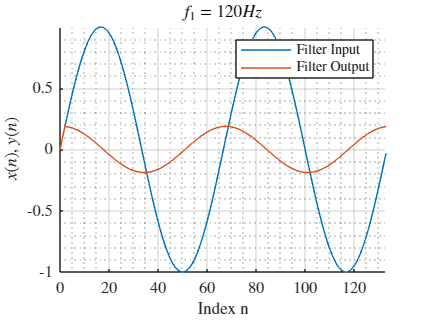

T = 1;
M = T/Ts;
n = 0:1:M-1; 

f1 = 120; 
f2 = 248; 

P1 = 2*round(fs/f1);
P2 = 2*round(fs/f2);

x1 = sin(2*pi*f1*Ts*n); 
y1 = filter(Z,N,x1);

x2 = sin(2*pi*f2*Ts*n); 
y2 = filter(Z,N,x2);

fig = figure;
set(fig,'color','w');
plot(n(1:P1),x1(1:P1));
hold on
plot(n(1:P1),y1(1:P1));
grid on; grid minor;
box off;
axis tight
xlabel('Index n','Interpreter','latex');
ylabel('$x(n), y(n)$','Interpreter','latex');
title('$f_1 = 120Hz$','Interpreter','latex','FontWeight','Normal');
legend('Filter Input','Filter Output','Interpreter','latex');

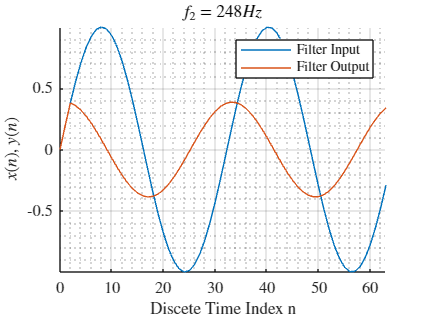


fig = figure;
set(fig,'color','w');
plot(n(1:P2),x2(1:P2));
hold on
plot(n(1:P2),y2(1:P2));
grid on; grid minor;
box off;
axis tight
xlabel('Discete Time Index n','Interpreter','latex');
ylabel('$x(n), y(n)$','Interpreter','latex');
title('$f_2 = 248Hz$','Interpreter','latex','FontWeight','Normal');
legend('Filter Input','Filter Output','Interpreter','latex');